clc; clear; close all;

v = [14.8442 13.8033 14.4093 16.1762 18.6913];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5850/2 * ones(size(v)) / 1000;

muestras = [2 3];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.8883    0.8716



rho = 1050;

x = eta_sol.^2

x =     0.7892    0.7598


y = rho*v.^2

y = 1.0e+05 *

    2.0006    2.1801


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -610448.7276 * x + 681801.7482


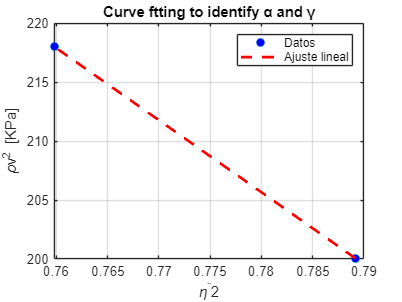


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 6.8180e+05

gamma = -m

gamma = 6.1045e+05


stress = alpha - gamma

stress = 7.1353e+04

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.0375

young = stress/strain

young = 1.9009e+06